# **Aerial Robotics**

Howdy participants!! 

Welcome to the **Aerial Robotics** course brought to you by the Aeromodelling Club !!

You must have often wondered how the micro air vehicles are made to exhibit agile and accurate operations autonomously even in highly cluttered environments. So, fasten your seatbelts, and this freezing winter get ready to dive into one of the hottest innovation fields of industry-  “AERIAL ROBOTICS” 

This course will take you through an interesting ride over the fascinating basics of aerial robotics in general including the kinematic and dynamic modeling of aerial systems and the design aspects of their control. At the end of this course as a whole you will be able to achieve the following learning objectives:

- Understand the basic kinematics of quadcopters

- Understand the domains and requirements of autonomous flights

- Formulate thrust requirements for the drone and size of its propulsion system

- PID for 1-D altitude quadrotor control

- Visualize and deal with Euler Angles and associated rotation matrices

- 2-D quadrotor control and controller design

- 3-D quadrotor control and controller design

The course is divided into 3 weeks where you will sequentially achieve the above objectives and implement them on basic problem statements. Every week, in addition to the given tutorials and practice problems, we will have an assignment based on that week’s material which will stimulate your thinking and help you get the most out of this course. These assignments will be sought in MATLAB and will be used for the course evaluation.

The course has been designed on MATLAB LiveScript. There are embedded links to the tutorials along with the textual explanations of the concepts. You will also get embedded examples at various instances during the course which will be executable in the liveScript simultaneously while learning. For this, we suggest you download MATLAB offline.

## **Week 0**

Welcome to Week 0!

Since the course has been designed on MATLAB and all the embedded tutorials, learning exercises, and assignments will be based on the same, it is important that before diving into the course content, you get familiar with the basics of MATLAB. This is what Week 0 deals with. So, the basic learning outcome for Week 0 is

- Get familiar with MATLAB basics

MATLAB as you may know is a powerful mathematical tool, which is used for a multitude of operations that involves plotting graphs, solving complex equations, formulating functions, controlling commands, and several more. In Aerial Robotics, we widely use MATLAB as an important platform to plot the different graphical characteristics for our system like the thrust requirement, relative positions, time-dependent configurations which govern the control of the system in various ways. 

Follow the below tutorials one by one and try solving the embedded exercises to get a good command over them. The participants who already have a good understanding of MATLAB can use it as a revision or stay tuned for the upcoming weeks :)

Happy Learning!

### **MATLAB Basics**

- [Matlab Variables](https://www.youtube.com/watch?v=L-Y8Q--I2YM)

Example:

age = 19;
code_name = 47;
CODE_NAME = 48;
age, code_name, CODE_NAME

age = 19

code_name = 47

CODE_NAME = 48

x = 2;
y = (4*(x^2))+(3*x)-7;
y

y = 15

5+(3*6)

ans = 23

- [Creating Vectors](https://www.youtube.com/watch?v=8OQyjKBo0kM)

Example:

x_1 = [-2, 0, 2];
x_2 = [-2; 0; 2];
x_1, x_2

x_1 =     -2     0     2


x_2 =     -2
     0
     2


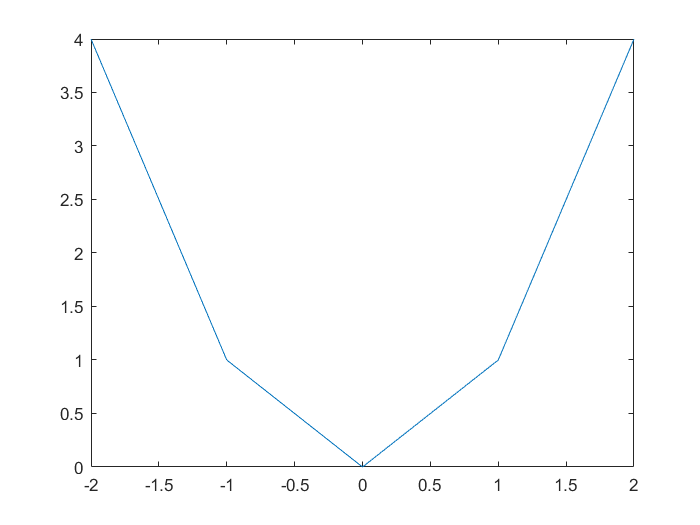

z = [-2, -1, 0, 1, 2];
w = [4, 1, 0, 1, 4];
plot(z, w)

- [Using the : operator](https://www.youtube.com/watch?v=-nnyr8jdoFg)

Example:

x_3 = -1:0.5:1;
x_4 = -1:0.3:1;
x_3, x_4

x_3 =    -1.0000   -0.5000         0    0.5000    1.0000


x_4 =    -1.0000   -0.7000   -0.4000   -0.1000    0.2000    0.5000    0.8000


x_5 = -1:1;
x_5 

x_5 =     -1     0     1


x_6 = (-1:1)';
x_6 

x_6 =     -1
     0
     1


-  [Functions](https://www.youtube.com/watch?v=2DZSBODL5oQ)

Example

x_7 = 1;
sin(x_7), log10(x_7), exp(x_7) 

ans = 0.8415

ans = 0

ans = 2.7183

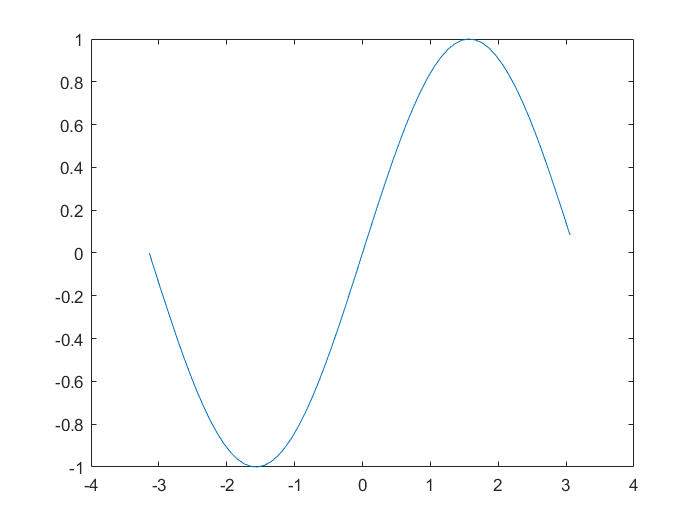

x_8 = -pi:0.1:pi;
y_8 = sin(x_8);
plot(x_8, y_8) 

[a, I] = min([1, 2 ,3 ,4, 5, -5]);
a, I 

a = -5

I = 6

you can always search for matlab documentation of a function.

- [Matlab as a calculator](https://www.youtube.com/watch?v=pdPnbSeUQAY)

Example

x1 = 5;
3*(x1^2)*((6-x1)^5) 

ans = 75

To solve $y=3x^2 +2x-1$, the solutions are $x=\frac{-b\pm \sqrt{b^2 -4\textrm{ac}}}{2a}$

a =3;
b = 2;
c = -1;
sol1 = (-b+sqrt((b^2)-(4*a*c)))/(2*a)

sol1 = 0.3333

sol2 = (-b-sqrt((b^2)-(4*a*c)))/(2*a)

sol2 = -1

[Calculations with vectors](https://www.youtube.com/watch?v=rWoYfSLF3rY)

Example

v1 = [1, 2, 3, 4, 5];
v2 = [3, 4, 5, 6, 7];
v1.*v2

ans =      3     8    15    24    35


v1./v2

ans =     0.3333    0.5000    0.6000    0.6667    0.7143


v1.^2

ans =      1     4     9    16    25


v1+v2 

ans =      4     6     8    10    12


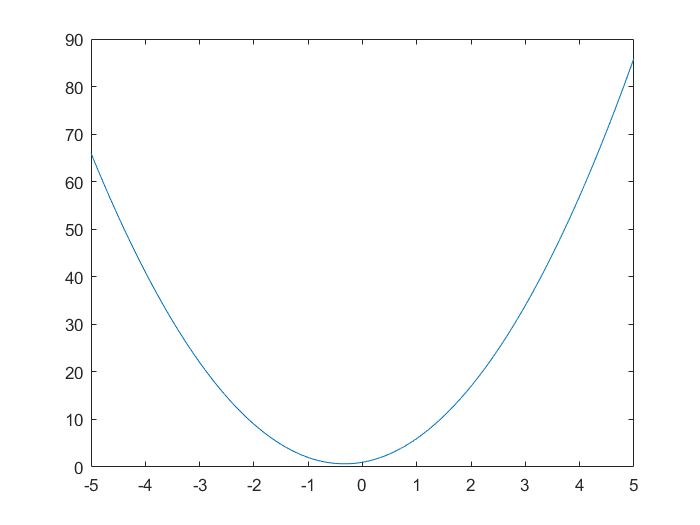

p = -5:0.1:5;
q = 3*(p.^2)+(2*p)+1; 
plot(p, q)
hold off;

- [Creating matrices](https://www.youtube.com/watch?v=uEaSPQz5-p0)

Examples

A = [1, 5, 7 ; 8, 0, 4] 

A =      1     5     7
     8     0     4


B = [11, 22, 33;
    44, 55, 66;
    77, 88, 99] 

B =     11    22    33
    44    55    66
    77    88    99


- [Matrix multiplication](https://www.youtube.com/watch?v=ooGBmqU6TVg)

Examples

C = [1, 3, 5;
    2, 4, 6;
    0, 4, 7];
u = [1; 2; 3];
C*u 

ans =     22
    28
    29


- [Logical operators](https://www.youtube.com/watch?v=bnMQZJbOBn8&feature=youtu.be)

Examples

s =3;
v = (s==3) | (s > 5) | (s < -12);
v 

v = logical
   1


1 & 1

ans = logical
   1


1 & 0

ans = logical
   0


1 | 1

ans = logical
   1


1 | 0

ans = logical
   1


0 | 0

ans = logical
   0


- [Conditional data selection](https://www.youtube.com/watch?v=xMfW-RVy4j4&feature=youtu.be)

Examples

e = -2:0.1:2;
E = sin(e);
L = E > 0;
R = E(L);
R

R =     0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093


- [FOR loop](https://www.youtube.com/watch?v=3cFv7vnb6KE&feature=youtu.be)

Example

M = [1 0 0 0 0 0 0 0]

M =      1     0     0     0     0     0     0     0


for n = 1:8
    M(n+1) = M(n)^2;
end

- [If-Else Statement](https://youtu.be/Iauqjo7qAOc)

Examples:

answer = 'Hi'

answer = 'Hi'

if answer == 'Hi'
    say = 'Hello';
elseif answer  == 'bye'
    say = 'bye';
else 
    say = '';
end
say

say = 'Hello'

%Note it is case sensitiv


- [Creating Multiple Plots](https://youtu.be/CKHN8xKN-Wk)

Examples:

%I wanna make a lattice of 10 vertical lines 
%ones you are encouraged to try it here, I'll skip some space...







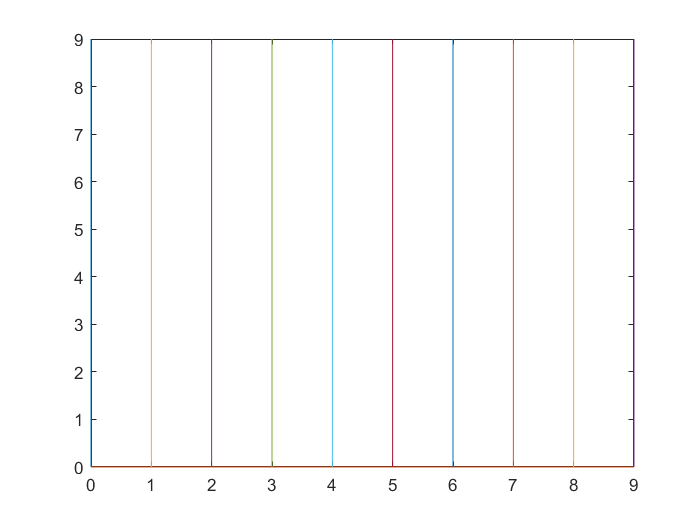

clear;
a1 = 0:1:9;
plot(zeros(10, 1),a1);
hold on;
plot(a1, zeros(10, 1));

for n = 1:9

   N = n.* ones(10,1); %to create an array of same elements
   
   
   plot(N,a1);
   
end

hold off;

- [Annotating the plots](https://youtu.be/0tQ_QKLgPqY)

Examples

%The video is self explainatory, and I recommend you to annotate the plots discussed above

- [Solving System of linear equations](https://youtu.be/UQk6HnuAtyc)

Example

%Now here I would rather prefer you attempt these, though I'll give one
%example still...
A = [1 0 0; 0 1 0; 0 0 1]

A =      1     0     0
     0     1     0
     0     0     1


b = [1; 2; 3]

b =      1
     2
     3


x = A\b

x =      1
     2
     3


% though quite obvious but still :-)

- [Symbolics](https://youtu.be/kNqtsuHBADM)

Examples

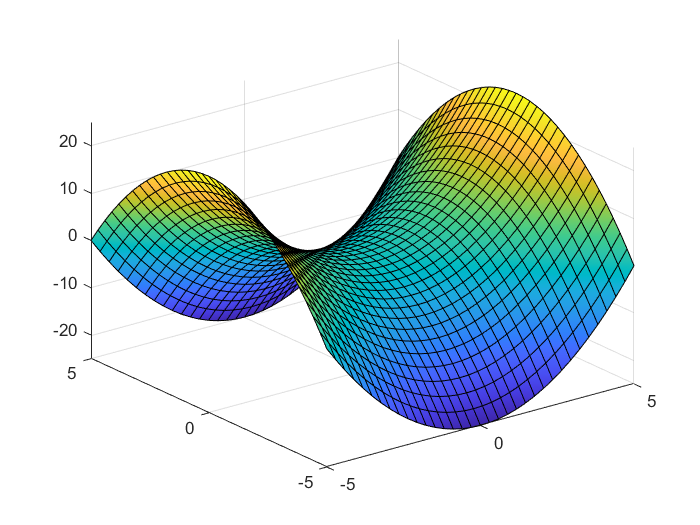

%For this I'll give you an example on plotting a function with saddle point
%which I am pretty sure you'll remember from calculus :-)
syms x y z
z(x,y) =x^2-y^2;
fsurf(z)

%Now let's have a look at the solution of z = 0.
solve(z == 0,x)

$$ans = \left(\begin{array}{c} y\\ -y \end{array}\right)$$

- [function as an input](https://youtu.be/MhPf5uP3tzs)

Example

%Now we can try and find how x^4-y^2 looks like just by using the result
%obtined in previous cells
f = @(l)l^2;
a = z(f,y)

$$a = l^{4}-y^{2}$$

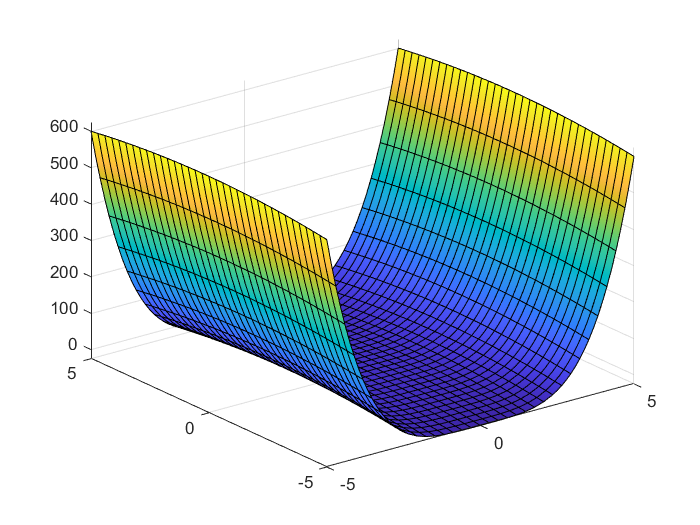

fsurf(a)

- [ODE45](https://youtu.be/GyGCn7Z4Xqg)

Examples:

%The easiest example is decay equation 
dNdt = @(t,N)-5*N;
tspan = [0,5]

tspan =      0     5


N0 = 10;
dNdt

dNdt = function_handle with value:
    @(t,N)-5*N


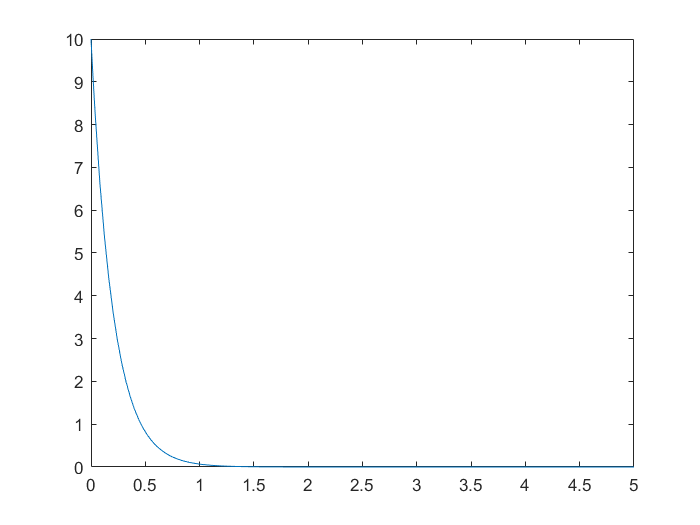

[tsol,Nsol] = ode45(dNdt,tspan,N0);
plot(tsol,Nsol)

- [higher order ode](https://youtu.be/fumznzFLjK8)

Examples

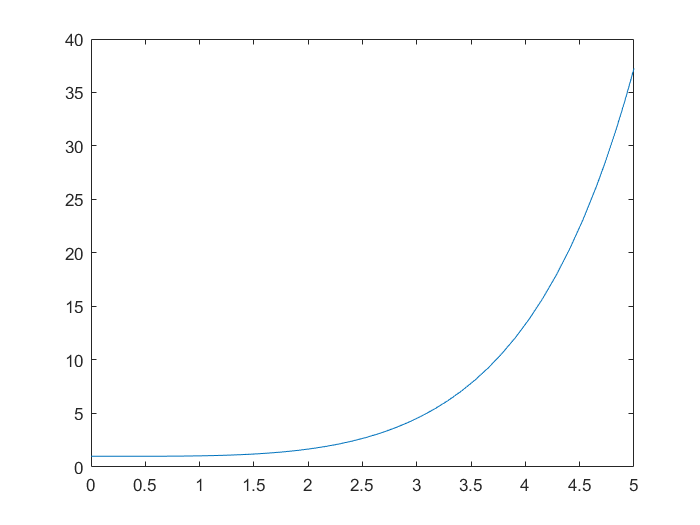

%For this let's use the fourth order equation : d4y/dx4 = y
dydx = @(x,y)[y(2);y(3);y(4);y(1)];
x = [0,5];
y0 = [1 0 0 0];
[xsol,ysol] = ode45(dydx,x,y0);
plot(xsol,ysol(:,1))

**Assignment:**

**Usually a system of equations are used to describe chemical reactions. One example for the same is :**

**dX/dt = k1AX - k2XY**

**dY/dt = k2XY-k3Y**

**dA/dt = -k1AX**

**Take k1,k2,k3 as 1**

**and initial concentration of every reactant as 5(ignore units for now)**

**Here X,Y and A are the reactant concentration plot them in a single graph w.r.t. time (0-10seconds)**

**These correspond to the series of chemical equation:**

**A+X --->2X;**

**X+Y---->2Y;**

**Y--->B;**